**Laboratorium 8 - Linearyzacja**

**Jakub Szczypek nr 405912**

**grupa 5 WEAIiIB air**

Zadanie 1

%wejścia - przykładowe wartości
Q = 8000 

Q = 8000

w = 0.4 

w = 0.4000

wi = 0.4 

wi = 0.4000

Ti = 293

Ti = 293


%stan początkowy
T0 = 293 

T0 = 293

V0 = 0.04 

V0 = 0.0400

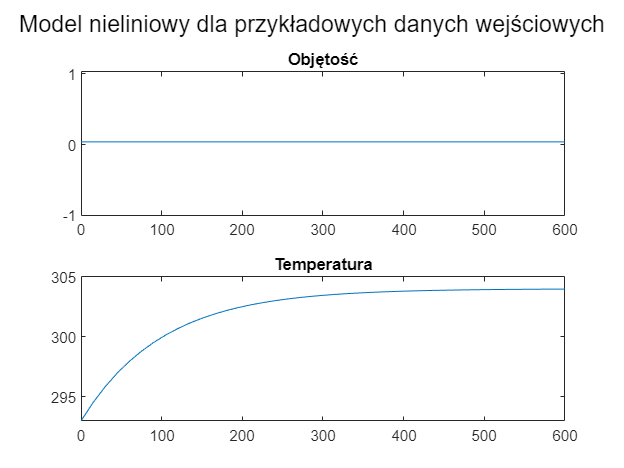


[t,x] = ode45(@zbiornik_stan, [0 600], [V0,T0], [], wi, w, Ti, Q);

hold on
subplot(2,1,1)
plot(t,x(:,1))
title('Objętość');

subplot(2,1,2)
plot(t,x(:,2))
title('Temperatura');
sgtitle('Model nieliniowy dla przykładowych danych wejściowych');
hold off

Zadanie 2

% znalezienie stanu ustalonego
X0=[0.04;303];
U0=[0.4;0.4;293;7000];
Y0=[0.04;303];
IX=[] ;
IU=[1;2;3];
IY=[1;2] ;

[x,u,y,dx]=trim('zbiornik_sys',X0,U0,Y0,IX,IU,IY)

x =     0.0400
  303.0000


u = 	1.0e+03 *

    0.0004
    0.0004
    0.2930
    7.2800


y =     0.0400
  303.0000


dx = 	1.0e+-14 *

         0
   -0.3025


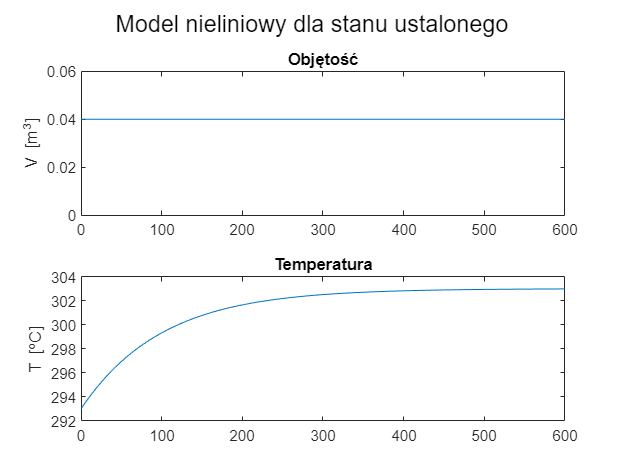


% wartości dla stanu ustalonego zawierają się w wektorze u
Q_ust = u(4);
wi = u(1);
w= u(2);
Ti = u(3);

[t2,x2] = ode45(@zbiornik_stan, [0:600], [V0,T0], [], wi, w, Ti, Q_ust);

figure
hold on
subplot(2,1,1)
plot(t2,x2(:,1));
ylim([0 0.06]);
ylabel('V [m^3]');
title('Objętość');

subplot(2,1,2)
plot(t2,x2(:,2));
ylim([292 304]);
ylabel('T [^{o}C]');
title('Temperatura');
sgtitle('Model nieliniowy dla stanu ustalonego');

hold off

T0 = 293 

T0 = 293

V0 = 0.04 

V0 = 0.0400

X0=[0.04;303];
U0=[0.4;0.4;293;7000];
Y0=[0.04;303];
IX=[] ;
IU=[1;2;3];
IY=[1;2] ;
[x,u,y,dx]=trim('zbiornik_sys',X0,U0,Y0,IX,IU,IY)

x =     0.0400
  303.0000


u = 	1.0e+03 *

    0.0004
    0.0004
    0.2930
    7.2800


y =     0.0400
  303.0000


dx = 	1.0e+-14 *

         0
   -0.3025




% model liniowy 
% transmitancje:
[A,B,C,D] = linmod('zbiornik_sys', x, u);
for iu = [1,2,3,4]
    [licz,mian] = ss2tf(A,B,C,D,iu);
    printsys(licz,mian);
end

 
num(1)/den = 
 
   0.001 s + 1e-05
   ---------------
     s^2 + 0.01 s
 
num(2)/den = 
 
   -0.25 s - 1.3344e-15
   --------------------
       s^2 + 0.01 s
 
num(1)/den = 
 
   -0.001 s - 1e-05
   ----------------
     s^2 + 0.01 s
 
num(2)/den = 
 
    1.3344e-15
   ------------
   s^2 + 0.01 s
 
num(1)/den = 
 
         0
   ------------
   s^2 + 0.01 s
 
num(2)/den = 
 
      0.01 s
   ------------
   s^2 + 0.01 s
 
num(1)/den = 
 
         0
   ------------
   s^2 + 0.01 s
 
num(2)/den = 
 
   1.3736e-05 s
   ------------
   s^2 + 0.01 s


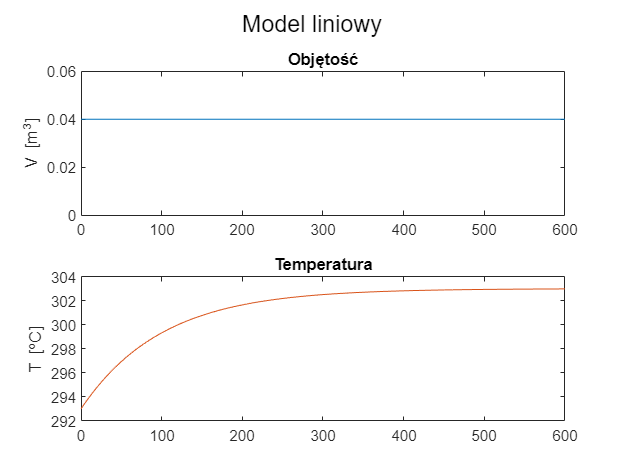


% odpowiedzi układu
X_pocz = [0.04; 293];
X_ust = [0.04; 303];
x0 = X_pocz - X_ust;
t = 0:1:600;
U = zeros(length(t),4);

y = lsim(A,B,C,D,U,t,x0);

hold on
subplot(2,1,1)
plot(t,y(:,1) + X_ust(1));
title('Objętość');
ylim([0 0.06]);
ylabel('V [m^3]');

subplot(2,1,2)
plot(t,y(:,2) + X_ust(2));
title('Temperatura');
ylabel('T [^{o}C]');
ylim([292 304]);
sgtitle('Model liniowy');
hold off

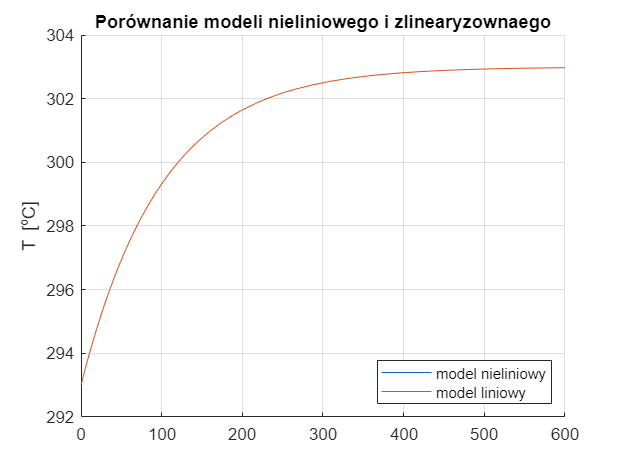

%porównanie
figure;
hold on
plot(t2,x2(:,2), t,y(:,2) + X_ust(2));
grid on;
ylabel('T [^{o}C]');
legend('model nieliniowy', 'model liniowy', "Location", 'southeast');
title('Porównanie modeli nieliniowego i zlinearyzownaego');
ylim([292 304]);
hold off

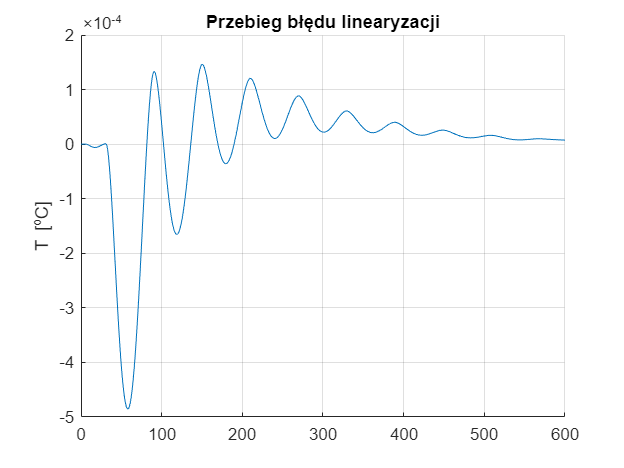

figure;
t = 0:1:600;
hold on
plot(t, y(:,2) + X_ust(2) - x2(:,2));
grid on;
ylabel('T [^{o}C]');
title('Przebieg błędu linearyzacji');
hold off